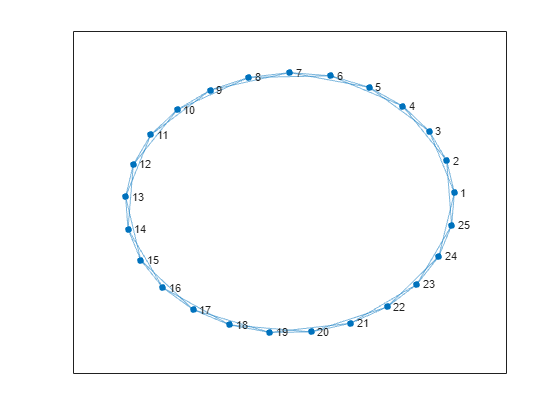

cs = 25 ; % class size
cn = 200 ; % number of classes

resultmm = cell(100, 4) ; % cell to collect result vectors
degs = zeros(100, 1) ; % network statistics
gstds = zeros(100, 1) ;
meanccs = zeros(100, 1) ;

% for loopno = 1:100 % loop 100 simulations

% creation of a single ring network
m = zeros(cs, cs) ; 
l = [0; ones(2, 1); zeros(cs - 5, 1); ones(2, 1)] ;
for c1 = 1:cs
    m(c1, :) = l ;
    l = circshift(l, 1) ;
end
plot(graph(m))

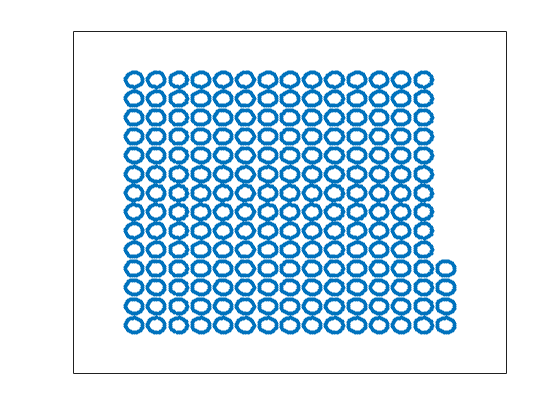

m = kron(eye(cn),m) ; % creation of adjacency matrix of many ring networks
ga = graph(m) ;
plot(ga)

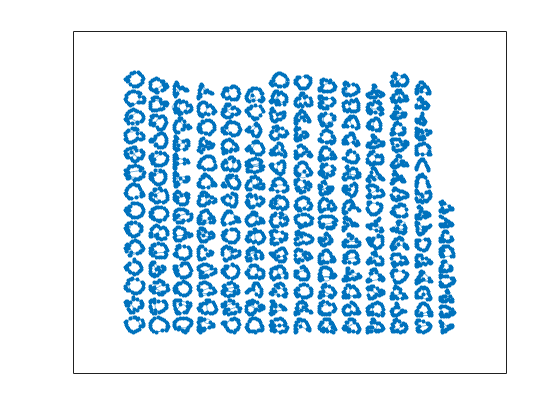

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [34.5302 33.9017 32.9750 32.7756 31.8941 31.7765 31.6482 31.5672 31.9153 32.1690 32.1170 32.5430 33.1369 33.2643 34.2472 34.8130 35.4434 36.0312 36.4590 36.7240 36.8050 36.6771 36.4081 35.8637 35.2118 81.6080 81.8219 … ] (1×5000 double)
         YData: [98.6364 99.5533 99.0289 99.2515 100.2547 100.1292 100.9647 100.8011 101.5768 102.9633 102.3861 103.0775 102.6186 103.3482 103.8258 104.1991 104.2440 103.7192 103.0017 102.0576 101.0371 100.0837 99.2219 98.8006 98.8037 … ] (1×5000 double)
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 


for it = 1:cn % loop through ring networks
    itn = (it - 1) * cs ;
    p = 0.2 ; % rewire nodes to make small world networks
    r = randperm(cs, cs*p) + (itn * 2) ;
    ep = ga.Edges.EndNodes(r, :) ;
    ga = ga.rmedge(r) ;
    for c2 = 1:(cs*p)
        r2 = randi(2) ;
        r3 = ep(c2, r2) ;
        while r3 == ep(c2, 1) || r3 == ep(c2, 2) 
            r3 = randi(cs) + itn ;
        end
        if r2 == 1
            ga = addedge(ga, ep(c2, 1), r3, 1) ;
        else
            ga = addedge(ga, r3, ep(c2, 2), 1) ;
        end
    end
end

p = plot(ga)

px = p.XData

px =    34.5302   33.9017   32.9750   32.7756   31.8941   31.7765   31.6482   31.5672   31.9153   32.1690   32.1170   32.5430   33.1369   33.2643   34.2472   34.8130   35.4434   36.0312   36.4590   36.7240   36.8050   36.6771   36.4081   35.8637   35.2118   81.6080   81.8219   81.8797   82.2477   81.8543   80.1632   80.4346   80.9346   81.2494   81.1379   80.9613   80.5245   80.1785   79.3260   78.7080   78.1559   77.8248   77.5905   78.0560   77.6844   78.3488   78.0422   78.6269   78.5827   80.2382


py = p.YData

py =    98.6364   99.5533   99.0289   99.2515  100.2547  100.1292  100.9647  100.8011  101.5768  102.9633  102.3861  103.0775  102.6186  103.3482  103.8258  104.1991  104.2440  103.7192  103.0017  102.0576  101.0371  100.0837   99.2219   98.8006   98.8037   43.2724   43.2820   43.8804   43.6122   44.4363   47.2348   46.2677   47.8336   48.4421   48.2830   48.1498   47.3733   45.9010   46.2841   45.9313   45.6030   45.7868   45.6535   45.8820   45.3317   45.2467   44.6960   44.2987   44.3780   43.5453



sc = 5 ; % social links
a = [ones(cs, 1); zeros(cs * (cn - 1), 1)] + 1 ;
for n = 1:cn % for every node
    for s = 1:cs
        p = round(exprnd(sc)) ; % exponential random number
        b = a ;
        b(((n - 1) * cs) + s) = 0 ;
        c = ones(p, 2) * ((n - 1) + s) ;
        c(:, 2) = datasample(1:(cs*cn), p, 'Weights', b, 'Replace', false) ;
        ga = addedge(ga, c(:,1), c(:,2), 1) ;
    end
    a = circshift(a, cs) ; % double the probability in every small-world network
end
ga = simplify(ga) ; % remove self-connections

gf = figure

gf =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


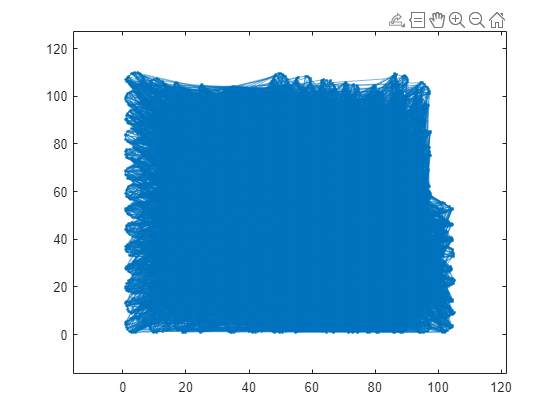

gpp =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 1
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.1000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [34.5302 33.9017 32.9750 32.7756 31.8941 31.7765 31.6482 31.5672 31.9153 32.1690 32.1170 32.5430 33.1369 33.2643 34.2472 34.8130 35.4434 36.0312 36.4590 36.7240 36.8050 36.6771 36.4081 35.8637 35.2118 81.6080 81.8219 … ] (1×5000 double)
         YData: [98.6364 99.5533 99.0289 99.2515 100.2547 100.1292 100.9647 100.8011 101.5768 102.9633 102.3861 103.0775 102.6186 103.3482 103.8258 104.1991 104.2440 103.7192 103.0017 102.0576 101.0371 100.0837 99.2219 98.8006 98.8037 … ] (1×5000 double)
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

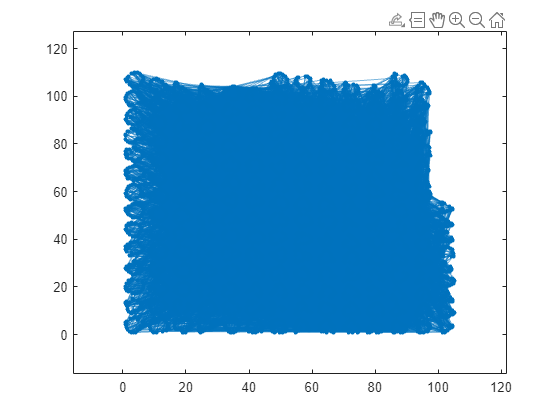

gpp = plot(ga, 'LineWidth', 0.1, 'MarkerSize', 1, 'XData', px, 'YData', py)

exportgraphics(gpp, 'netimage.png')

Error using exportgraphics
First parameter must specify the axes or chart object.


degvec = degree(ga) ;

degs(loopno) = mean(degree(ga)) ;
gstds(loopno) = std(degree(ga))  ;

gpp = plot(ga, 'LineWidth', 0.1, 'MarkerSize', 0.4, 'XData', px, 'YData', py)

gpp =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 0.4000
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.1000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [34.5302 33.9017 32.9750 32.7756 31.8941 31.7765 31.6482 31.5672 31.9153 32.1690 32.1170 32.5430 33.1369 33.2643 34.2472 34.8130 35.4434 36.0312 36.4590 36.7240 36.8050 36.6771 36.4081 35.8637 35.2118 81.6080 81.8219 … ] (1×5000 double)
         YData: [98.6364 99.5533 99.0289 99.2515 100.2547 100.1292 100.9647 100.8011 101.5768 102.9633 102.3861 103.0775 102.6186 103.3482 103.8258 104.1991 104.2440 103.7192 103.0017 102.0576 101.0371 100.0837 99.2219 98.8006 98.8037 … ] (1×5000 double)
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

[eid, nid] = ga.outedges(104)

eid =         1695
        3036
        3159
        6339
        8609
       11205
       11421
       11531
       11638
       11639


nid =     26
    36
    37
    62
    80
   100
   102
   103
   106
   107


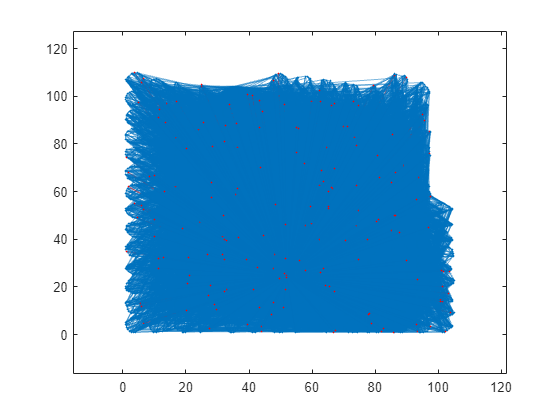

highlight(gpp, ga.neighbors(104), 'NodeColor', 'red') ;
highlight(gpp, ones(203, 1) .* 104, nid, 'EdgeColor', 'red') ;


for iscount = 1:4 % change isolation strategy

tl = cs * cn ; % total population

delta = 1/14 ; % epidemic rate parameters
gamma = 1/11 ;
epsilon = 1/5.2 ;
beta = 2.2 / 11 ;
beta2 = 0.05.*beta ;
 
nettm = adjacency(ga) ;

pseed = 10 ; % seed starting infections
e1vec = zeros(1, tl) ;
e2vec = zeros(1, tl) ; 
e1vec(randperm(tl, pseed./2)) = 1 ;
e2vec(randperm(tl, pseed./2)) = 1 ;

isovec = zeros(1, tl) ; % vectors for tracking nodes in each state
ivec = zeros(1, tl) ;
svec = ones(1, tl) - ivec ;
rvec = zeros(1, tl) ;

resultm = [] ;

t = 0 ;
tthr = 0 ;
isothr = 1/48 ;
while sum(ivec)+sum(e1vec)+sum(e2vec) > 0 % loop until no infection
    if t >= tthr
        figure()
        gap = plot(ga, 'layout', 'force', 'UseGravity', true) ;
        highlight(gap, nonzeros((1:tl) .* svec), 'NodeColor', 'green') ;
        highlight(gap, nonzeros((1:tl) .* rvec), 'NodeColor', 'blue') ;
        highlight(gap, nonzeros((1:tl) .* isovec), 'NodeColor', 'cyan') ;
        highlight(gap, nonzeros((1:tl) .* e1vec), 'NodeColor', 'yellow') ;
        highlight(gap, nonzeros((1:tl) .* e2vec), 'NodeColor', 'magenta') ;
        highlight(gap, nonzeros((1:tl) .* ivec), 'NodeColor', 'red') ;
        tthr = tthr + 1 ;
    end

    % calculate event rates
    is = ( ivec * nettm ) .* svec ;
    infrate = beta .* sum(is) ;
    e1s = ( e1vec * nettm ) .* svec ;
    e1rate = beta2 .* sum(e1s) ;
    e2s = ( e2vec * nettm ) .* svec ;
    e2rate = beta2 .* sum(e2s) ;

    e1isorate = epsilon .* sum(e1vec) ;
    e2isyrate = epsilon .* sum(e2vec) ;

    isorate = delta .* sum(ivec) ;
    recrate = gamma .* sum(ivec) ;
    
    totrate = infrate + e1rate + e2rate + e1isorate + e2isyrate + isorate + recrate ;
    % randomly select the event type
    r = rand .* totrate ;
    p = randsample([1, 2], 1) ;

    if r >= (infrate + e1rate + e2rate + e1isorate + e2isyrate)
        if r >= (totrate - recrate) % i_sym to rec
            recec = randsample(1:tl, 1, true, ivec) ;
            ivec(recec) = 0 ;
            rvec(recec) = 1 ;
        else % i_sym to iso
            recec = randsample(1:tl, 1, true, ivec) ;
            ivec(recec) = 0 ;
            isovec(recec) = 1 ;
        end
    elseif r >= (infrate + e1rate + e2rate)
        if r >= (infrate + e1rate + e2rate + e1isorate) % e2 to i_sym
            recec = randsample(1:tl, 1, true, e2vec) ;
            e2vec(recec) = 0 ;
            ivec(recec) = 1 ;
        else % e1 to iso
            recec = randsample(1:tl, 1, true, e1vec) ; %
            e1vec(recec) = 0 ;
            isovec(recec) = 1 ;
        end
    else
        if r >= (infrate + e1rate) % s to e1 or e2 at random via e2 interaction
            recec = randsample(1:tl, 1, true, e2s) ;
            svec(recec) = 0 ;
            if p == 2
                e2vec(recec) = 1 ;
            else
                e1vec(recec) = 1 ;
            end
        elseif r >= infrate % s to e1 or e2 at random via e1 interaction
            recec = randsample(1:tl, 1, true, e1s) ;
            svec(recec) = 0 ;
            if p == 2
                e2vec(recec) = 1 ;
            else
                e1vec(recec) = 1 ;
            end
        else % s to e1 or e2 at random via i interaction
            recec = randsample(1:tl, 1, true, is) ;
            svec(recec) = 0 ;
            if p == 2
                e2vec(recec) = 1 ;
            else
                e1vec(recec) = 1 ;
            end
        end
    end

    % isolation strategy
    if ( sum(svec) < (tl - cs) ) && (t > tthr) && ( sum(is) ~= 0 ) % needs to be over the infection level threshold
        tthr = t + isothr ;
        switch iscount % switch isolation strategy
            case 2 % ct
                randct = randsample(1:tl, 1, true, is) ;
                svec(randct) = 0 ;
                isovec(randct) = 1 ;
            case 3 % and one
                randct = randsample(1:tl, 1, true, is) ;
                r = zeros(1, tl) ;
                r(randct) = 1 ;
                rctvec = ( r * nettm ) .* svec ;
                if sum(rctvec) ~= 0
                    randct = randsample(1:tl, 1, true, rctvec) ;
                    svec(randct) = 0 ;
                    isovec(randct) = 1 ;
                end
            case 4 % degree
                randct = randsample(1:tl, 1, true, degvec' .* svec) ;
                svec(randct) = 0 ;
                isovec(randct) = 1 ;
        end
    end

    t = t + (- log(rand) ./ totrate) ; % serial interval function

    resultm = [resultm;t,sum(svec),sum(e1vec),sum(e2vec),sum(ivec),sum(isovec),sum(rvec)] ; % add to data table
end

% resultmm{loopno, iscount} = resultm ;

end

% svec
% sum(svec)
% isovec
% sum(isovec)
% rvec
% sum(rvec)
% t

% figure()
%         gap = plot(ga, 'layout', 'force', 'UseGravity', true) ;
%         highlight(gap, nonzeros((1:tl) .* svec), 'NodeColor', 'green') ;
%         highlight(gap, nonzeros((1:tl) .* rvec), 'NodeColor', 'blue') ;
%         highlight(gap, nonzeros((1:tl) .* isovec), 'NodeColor', 'cyan') ;
%         highlight(gap, nonzeros((1:tl) .* e1vec), 'NodeColor', 'yellow') ;
%         highlight(gap, nonzeros((1:tl) .* e2vec), 'NodeColor', 'magenta') ;
%         highlight(gap, nonzeros((1:tl) .* ivec), 'NodeColor', 'red') ;

%if loopno > 99 % graph individual simulations to ensure success
figure
hold on
col= {'a', 'green', 'yellow', 'magenta', 'red', 'cyan', 'blue'}
for c = 2:7
scatter(resultm(:, 1), resultm(:, c), 'filled', 'Color', col{c})
end
hold off
legend('s', 'e1', 'e2', 'i_sym', 'iso', 'r')

figure
hold on
cola = [1, 1, 1, 0, 0, 0] ;
colb = [1, 0, 0, 1, 1, 0] ;
colc = [0, 1, 0, 1, 0, 1] ;
for c = 2:7
plot(resultmm{2}(:, 1), resultmm{2}(:, c), 'LineWidth', 2, 'Color', [cola(c-1), colb(c-1), colc(c-1)])
end
hold off
legend('s', 'e1', 'e2', 'i_sym', 'iso', 'r')

figure
hold on
cola = [1, 1, 1, 0, 0, 0] ;
colb = [1, 0, 0, 1, 1, 0] ;
colc = [0, 1, 0, 1, 0, 1] ;
for c = 2:7
plot(resultmm{3}(:, 1), resultmm{3}(:, c), 'LineWidth', 2, 'Color', [cola(c-1), colb(c-1), colc(c-1)])
end
hold off
legend('s', 'e1', 'e2', 'i_sym', 'iso', 'r')

figure
hold on
cola = [1, 1, 1, 0, 0, 0] ;
colb = [1, 0, 0, 1, 1, 0] ;
colc = [0, 1, 0, 1, 0, 1] ;
for c = 2:7
plot(resultmm{4}(:, 1), resultmm{4}(:, c), 'LineWidth', 2, 'Color', [cola(c-1), colb(c-1), colc(c-1)])
end
hold off
legend('s', 'e1', 'e2', 'i_sym', 'iso', 'r')
%end
% end


resultmm ; % extract metrics out of data
maxinf = zeros(100, 4) ;
sleft = zeros(100, 4) ;
terad = zeros(100, 4) ;
conco = zeros(100, 4) ;
for col = 1:4
    for row = 1:100
        ts = resultmm{row, col} ;
        tsinf = ts(:, 3) + ts(:, 4) + ts(:, 5) ;
        maxinf(row, col) = max(tsinf) ;
        sleft(row, col) = ts(end, 2) ;
        terad(row, col) = ts(end, 1) ;
        conco(row, col) = ts(end, 6) / ts(end, 7) ;
    end
end

mean(maxinf, 1) % descriptive statistics about infection peaks
std(maxinf, 1)
prctile(maxinf, [0, 10, 25, 50, 75, 90, 100], 1)
[h,p] = ttest(maxinf(:, 1), maxinf(:, 2))
[h,p] = ttest(maxinf(:, 1), maxinf(:, 3))
[h,p] = ttest(maxinf(:, 1), maxinf(:, 4))
[h,p] = ttest(maxinf(:, 2), maxinf(:, 3))
[h,p] = ttest(maxinf(:, 2), maxinf(:, 4))
[h,p] = ttest(maxinf(:, 3), maxinf(:, 4))

figure % violin plots of descriptive statistics
violin(maxinf) ;
title('Violin plot of maximum infection levels in the population')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Number of people')

figure
violin(terad) ;
title('Violin plot of epidemic duration')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Days')

figure
violin(conco) ;
title('Violin plot of Iso / R')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Ratio')

figure
violin(sleft) ;
title('Violin plot of non-disrupted individuals')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Number of people')

resultmm2 ; % large scale isolation stats and graphs
maxinf2 = zeros(100, 4) ;
terad2 = zeros(100, 4) ;
conco2 = zeros(100, 4) ;
sleft2 = zeros(100, 4) ;
for col = 1:4
    for row = 1:100
        ts = resultmm2{row, col} ;
        tsinf = ts(:, 3) + ts(:, 4) + ts(:, 5) ;
        maxinf2(row, col) = max(tsinf) ;
        terad2(row, col) = ts(end, 1) ;
        conco2(row, col) = ts(end, 6) / ts(end, 7) ;
        sleft2(row, col) = ts(end, 2) ;
    end
end

figure
violin(maxinf2) ;
title('Violin plot of maximum infection levels in the population')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Number of people')

figure
violin(terad2) ;
title('Violin plot of epidemic duration')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Days')

figure
violin(conco2) ;
title('Violin plot of Iso / R')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Ratio')

figure
violin(sleft2) ;
title('Violin plot of non-disrupted individuals')
xticks(1:4)
xticklabels({'Nat', 'ConTra', 'And-One', 'Degree'})
axis('padded')
xlabel('Isolation Strategy')
ylabel('Number of people')

mean(maxinf2, 1)
std(maxinf2, 1)
prctile(maxinf2, [0, 10, 25, 50, 75, 90, 100], 1)
[h,p] = ttest(maxinf2(:, 1), maxinf2(:, 2))
[h,p] = ttest(maxinf2(:, 1), maxinf2(:, 3))
[h,p] = ttest(maxinf2(:, 1), maxinf2(:, 4))
[h,p] = ttest(maxinf2(:, 2), maxinf2(:, 3))
[h,p] = ttest(maxinf2(:, 2), maxinf2(:, 4))
[h,p] = ttest(maxinf2(:, 3), maxinf2(:, 4))
[h,p] = ttest(maxinf2(:, 1), maxinf(:, 1))
[h,p] = ttest(maxinf2(:, 1), maxinf(:, 2))
[h,p] = ttest(maxinf2(:, 1), maxinf(:, 3))
[h,p] = ttest(maxinf2(:, 1), maxinf(:, 4))
[h,p] = ttest(maxinf2(:, 2), maxinf(:, 1))
[h,p] = ttest(maxinf2(:, 2), maxinf(:, 2))
[h,p] = ttest(maxinf2(:, 2), maxinf(:, 3))
[h,p] = ttest(maxinf2(:, 2), maxinf(:, 4))
[h,p] = ttest(maxinf2(:, 3), maxinf(:, 1))
[h,p] = ttest(maxinf2(:, 3), maxinf(:, 2))
[h,p] = ttest(maxinf2(:, 3), maxinf(:, 3))
[h,p] = ttest(maxinf2(:, 3), maxinf(:, 4))
[h,p] = ttest(maxinf2(:, 4), maxinf(:, 1))
[h,p] = ttest(maxinf2(:, 4), maxinf(:, 2))
[h,p] = ttest(maxinf2(:, 4), maxinf(:, 3))
[h,p] = ttest(maxinf2(:, 4), maxinf(:, 4))